%load splat
%soundsc(y,Fs)

files = dir('C:\Users\sebas\Documents\GitHub\audios');
sound_files = struct();

c = 1;
for i=1:1:length(files)
    if contains(files(i).name,'wav') == 1
        sound_files(c).name = files(i).name;
        c = c+1;
    end
end
file = sound_files(1).name;
[s, fs] = audioread(['Files\' file]);

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 137)
    [y, Fs] = readaudio (filename, range, datatype);

%sound_files.name

sg = 400; ov = 300;

clf
spectrogram(s,sg,ov,[],fs,'yaxis');
view([64 67])
colormap bone
[s,f,t,p]  = spectrogram(s,sg,ov,[],fs,'yaxis');


clf
c = 0.0001;
p(p < max(max(p))*c | p==max(max(p))*c) = max(max(p))*c;
p(p > max(max(p)) | p==max(max(p))) = max(max(p));

imagesc(t,f,pow2db(p))
axis xy
view(0,90) %view([64 67])
colormap bone
colorbar

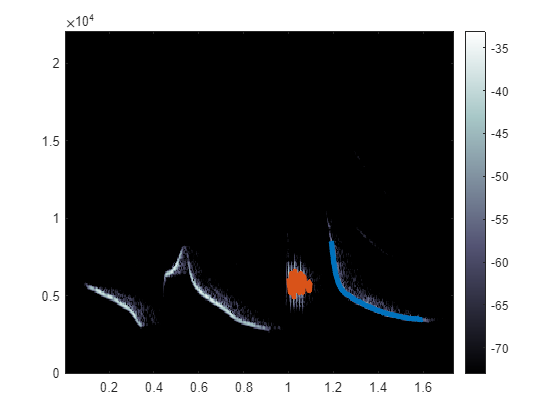

f1 = f < 10000; t1 = t < 1.1 & t > 1.0;
m1 = medfreq(p(f1,t1), f(f1));

%clf
hold on
plot(t(t1),m1,'linewidth',4)
hold off

p

p = 1.0e-03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

%sum(pow2db(p), dim=2)

%plot(s)
%{

f1 = f < 7500; t1 = 0.1 < t & t < 0.4;
m1 = medfreq(p(f1,t1),f(f1));

f2 = f < 7500; t2 = t > 0.4 & t < 0.9;
m2 = medfreq(p(f2,t2),f(f2));

%figure
hold on
%spectrogram(s,sg,ov,[],fs,'yaxis')
%view(0,90) %view([64 67])
%colormap bone
plot(t(t1),m1/1000,'linewidth',4)
plot(t(t2),m2/1000,'linewidth',4)
hold off
%}
